## Richardson's Arms Race model

Nation X will change its level of armament Xt according to the following process:

∆Xt = kYt – a*Xt + g

where:

- Xt = the armament level in nation X at year t

- Yt = the armament level in nation Y at year t

- a = the economic burden experienced by nation X in attempting to maintain its armament level

- k = the threat felt by nation X due to the armament level of nation Y

- g = the effect of ambitions, prejudices, and hostilities upon the armament level of nation X

Simultaneously, nation Y makes similar decisions regarding its own future armament levels according to the same rules. With only minor modification, the armament behavior of nation Y can be expressed as:

∆Yt = k’Xt – a’*Yt + g’

For full description of the model and procedured described below, please see chapter 4 of Huckfeldt, Kohfeld, & Likens (1982).

## Fixed point evaluation:

close all
syms f1(x) f2(x) 
a = 0.6;
k = 0.9;
g = 0.1;

a1 = 0.8;
k1 = 0.4;
g1 = 0.1;

f1(x) = (a/k)*x-(g/k);
f2(x) = (k1/a1)*x+(g1/a1);

% stability criterion; stable if a1*a is greater than k*k1
a1*a > k*k1

ans = logical
   1


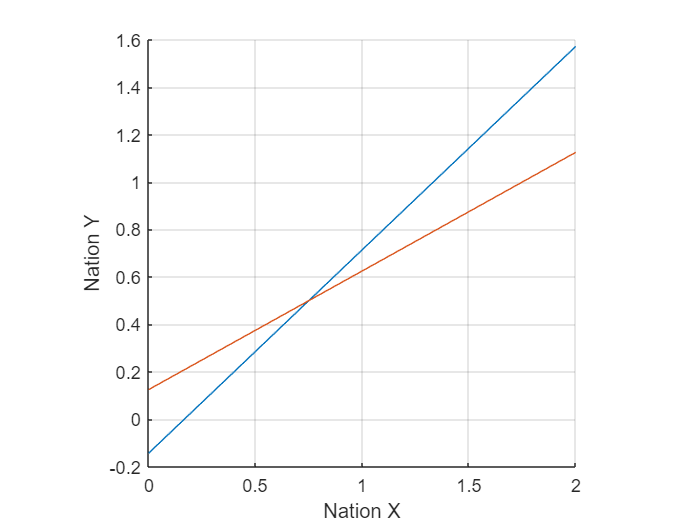

figure 
hold on
% xlim([0,1.5])
% ylim([0,1])
xlabel('Nation X')
ylabel('Nation Y')
axis square
grid on
fplot(f1(x),[0 2])
fplot(f2(x),[0 2])

Numerical iteration to observe behavior around the fixed point:

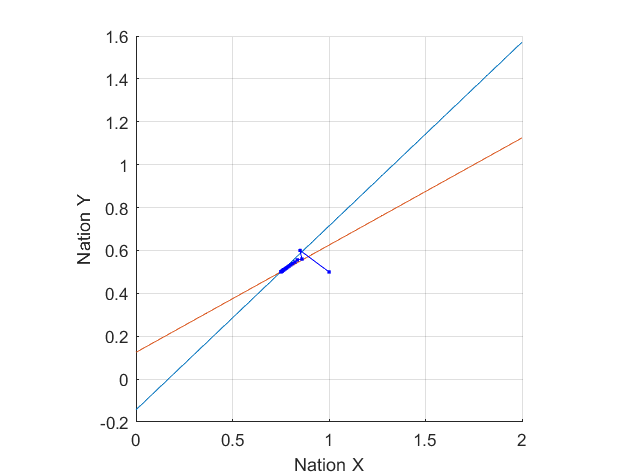

xt(1) = 1;
yt(1) = .5;

for i = 1:100
    xt(i+1) = k*yt(i)+(1-a)*xt(i)+g;
    yt(i+1) = k1*xt(i)+(1-a1)*yt(i)+g1;
    
    plot([xt(i) xt(i+1)],[yt(i) yt(i+1)],'b.-') 
    pause(0.01)
end


% plot(xt,yt,'b.-')